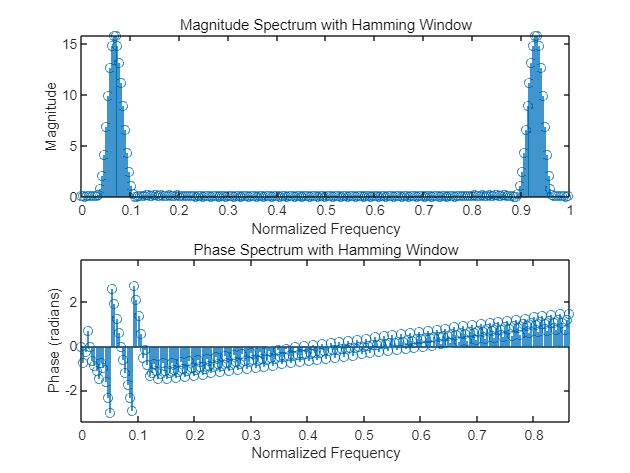

% LAB 2.2.5.3 刘兴琰 AI1 202264690069
N = 64;
N_padded = 256;

k = 0:N-1;

x_k = cos(2 * pi * k / 15) + 0.75 * cos(2.3 * pi * k / 15);

window = hamming(N);

x_k_windowed = x_k .* window';

x_k_windowed_padded = [x_k_windowed zeros(1, N_padded - N)];

X_k_windowed_padded = fft(x_k_windowed_padded, N_padded);

freq_padded = (0:N_padded-1) / N_padded;

subplot(2, 1, 1);
stem(freq_padded, abs(X_k_windowed_padded));
title('Magnitude Spectrum with Hamming Window');
xlabel('Normalized Frequency');
ylabel('Magnitude');

subplot(2, 1, 2);
stem(freq_padded, angle(X_k_windowed_padded));
title('Phase Spectrum with Hamming Window');
xlabel('Normalized Frequency');
ylabel('Phase (radians)');

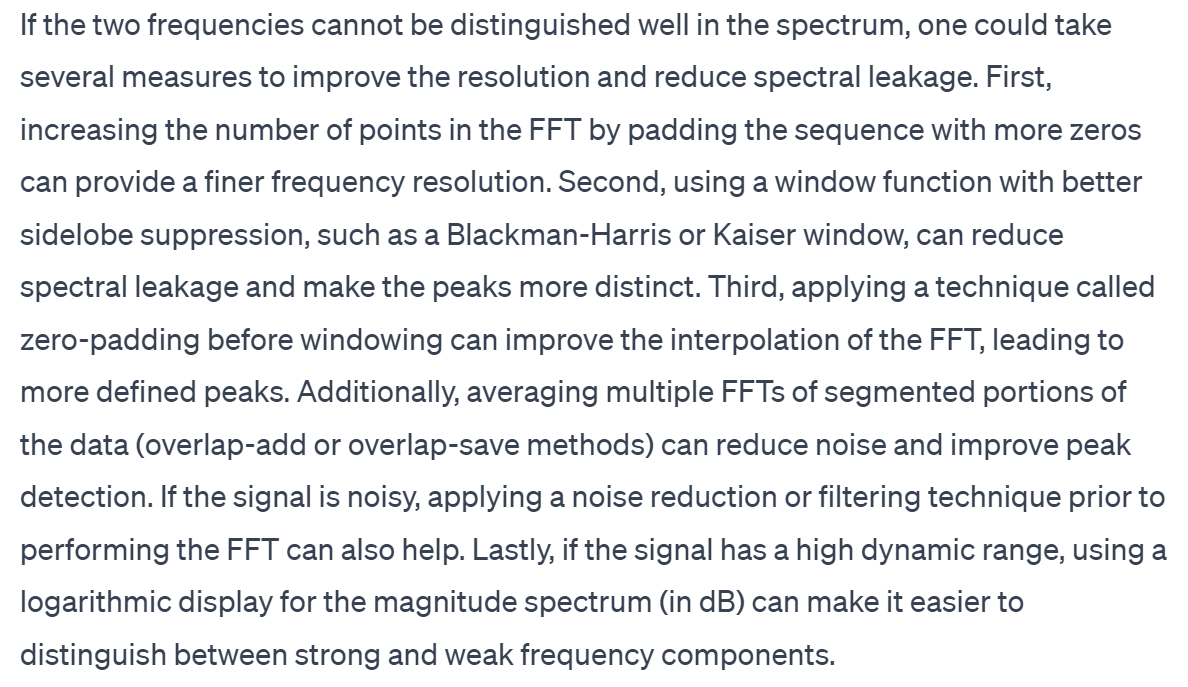

% LAB 2.2.5.4 刘兴琰 AI1 202264690069